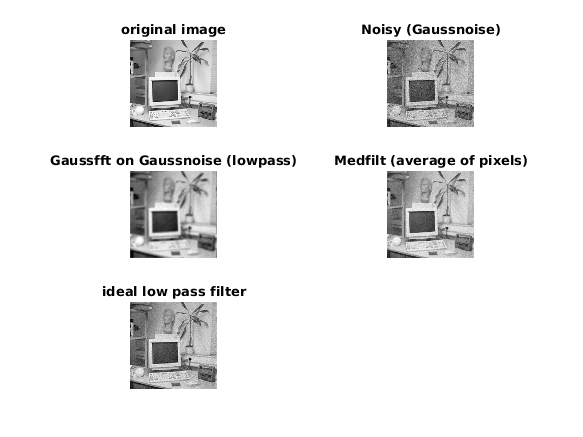

office = office256;
figure;
subplot(3,2,1)
showgrey(office) % original image
title("original image")


add = gaussnoise(office, 16); % noisy images
subplot(3,2,2)
showgrey(add) % add gaussian noise 
title("Noisy (Gaussnoise)")

subplot(3,2,3)
showgrey(gaussfft(add, 4)) % filter our gaussian noise. 
title("Gaussfft on Gaussnoise (lowpass)")
subplot(3,2, 4)

showgrey(medfilt(add,3)) % takes average of a set of pixels. 
title("Medfilt (average of pixels)")

subplot(3,2,5) 
showgrey(ideal(add, 0.3)) % low pass, not as bright?
title("ideal low pass filter")



disp("second filter type!")

second filter type!


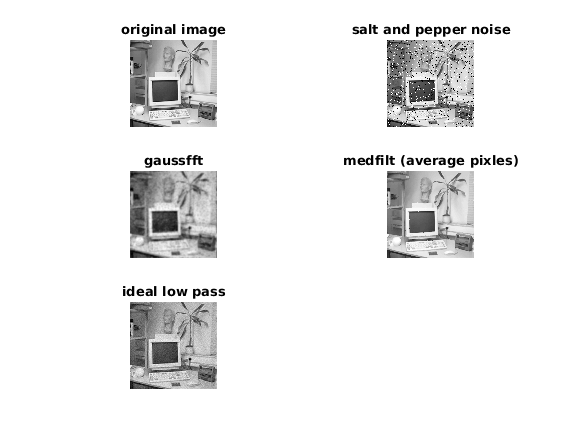

figure;
subplot(3,2,1)
showgrey(office) % original image
sap = sapnoise(office, 0.1, 255);% the othe noisy image
title("original image")

subplot(3,2,2)
showgrey(sap) % salt and pepper noise, random destoryted pixles
title("salt and pepper noise")

subplot(3,2,3)
showgrey(gaussfft(sap, 4)) % smooth with gaussfit
title("gaussfft")

subplot(3,2,4)
showgrey(medfilt(sap, 3)) % average set of pixels 
title("medfilt (average pixles)")

subplot(3,2,5)
showgrey(ideal(add, 0.3))
title("ideal low pass")